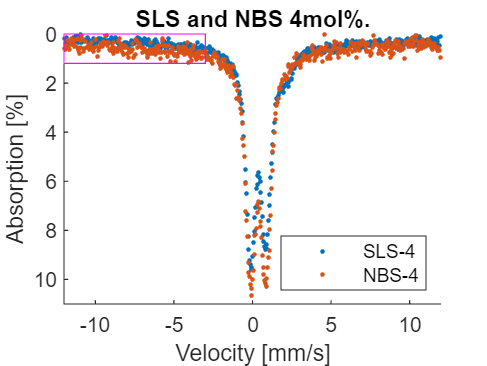

%clear crap
clear all

%importing data
SLS_4 = readtable("Year 3/Mossbauer/Archive/2212141016_SLS_4_raw_020323.csv");
NBS_4 = readtable("Year 3/Mossbauer/Archive/2212161041_NBS_4_raw_020323.csv");

%%SLS4
%calculating percentage absorption
max_y = max(table2array(SLS_4(:,2))); %extracting max y value for perc. absorbed calc
SLS_4.Var3=zeros(height(SLS_4),1);
%calculating perc absorption
for i = 1:1:height(SLS_4)
    SLS_4(i,3) = array2table(100*(max_y - table2array(SLS_4(i,2)))/max_y);
end

%%NBS4
%calculating percentage absorption
max_y = max(table2array(NBS_4(:,2))); %extracting max y value for perc. absorbed calc
NBS_4.Var3=zeros(height(NBS_4),1);
%calculating perc absorption
for i = 1:1:height(NBS_4)
    NBS_4(i,3) = array2table(100*(max_y - table2array(NBS_4(i,2)))/max_y);
end

%extracting x & y data
SLS_4_x = table2array(SLS_4(:,1));
SLS_4_y = table2array(SLS_4(:,3));
NBS_4_x = table2array(NBS_4(:,1));
NBS_4_y = table2array(NBS_4(:,3));

%plotting data
plot(SLS_4_x,SLS_4_y,".")
hold on %plotting on the same graph
plot(NBS_4_x,NBS_4_y,".")

%setting limits
xlim([-12 12])
ylim([0 11])

%beautifying curve
ax = gca;
box off;
set(gca, 'YDir','reverse') %inverting y axis

%labelling graph
xlabel("Velocity [mm/s]");
ylabel("Absorption [%]");
title("SLS and NBS 4mol%.")
legend("SLS-4","NBS-4","Location","SouthEast")

%zoom in square start pts and dim
x = -12;
y = 0;
w = 12-3 ;
h = 1.2;

%zoom in square
rectangle("Position",[x y w h],"EdgeColor","magenta")

hold off %ending plot 

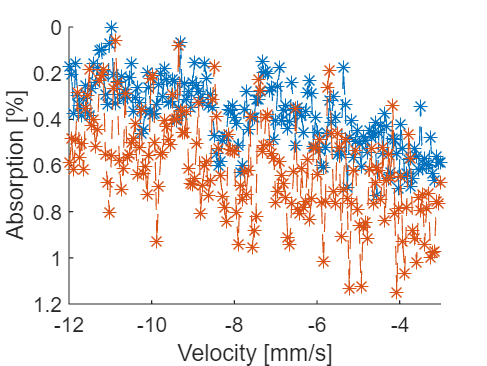


%second plot
plot(SLS_4_x,SLS_4_y,"--*")
hold on %plotting on the same graph
plot(NBS_4_x,NBS_4_y,"--*")

%setting zoom in limits
xlim([x x+w])
ylim([y h])

%beautifying curve
ax = gca;
box off;
set(gca, 'YDir','reverse') %inverting y axis

%labelling graph
xlabel("Velocity [mm/s]");
ylabel("Absorption [%]");

hold off %ending plot 